# Check Simulated Output Rates

Clear the workspace and command window.

clear; clc;

## Parameters

Once parameters are set as desired, click **Run** button below:

### Numeric/Experimental Parameters

Set different experimental parameters using sliders.

#### First set of parameters affects noise jitter (ms) of alignment

sigma_jitter_low = 20;

sigma_jitter_low = 20

sigma_jitter_high = 120;

sigma_jitter_high = 120

#### Next noise parameter is the white-noise process amplitude for spiking

sigma_rate_all = 10;

sigma_rate_all = 10

#### With more trials, jitter is more likely to average out in the mean plots

nTrials = 25;

nTrials = 25

#### The last two parameters determine number of channels and maximum number of factors per channel

nChannels = 16;

nChannels = 16

nFactor_max = 3;

nFactor_max = 3

### Figure Parameters

low_tag = ['\sigma_j =' sprintf('%3.0f-ms | N =%3.0f',sigma_jitter_low,nTrials)];
high_tag = ['\sigma_j =' sprintf('%3.0f-ms | N =%3.0f',sigma_jitter_high,nTrials)];
line_params.Low = {'Color','k','DisplayName',low_tag,'LineWidth',1.5};
line_params.High = {'Color',[0.5 0.5 0.5],'DisplayName',high_tag,'LineWidth',1.5};

## Create Data

### Load rate "factors" from file

[factors,t,mask] = data.io.load_factors();

In the default source data, there are **four **factors (rows of the `factors` matrix). Each factor was estimated using the Top-4 Principal Components from 32 simultaneously-sampled channels of grasp-task-aligned spike rates from motor cortical regions in a rat performing a non-head-fixed pellet retrieval reach-to-grasp behavior. Columns represent the average (smoothed) time-series scores for those coefficients. 

### Generate factor combinations for each channel

factor_combinations = data.sim.factor_sets(...
    nChannels,...      % Each "channel" is some weighted combination of factors
    nFactor_max,...    % Sets maximum # weighted factors per channel
    size(factors,1));  % Sets maximum factor "index"

### Define noise distributions

Each "noise-level" gets two different **Zero-Mean** Gaussian noise sources:

- **Temporal jitter** in apparent alignment of data (e.g. if video frame was scored a frame or two early or late compared to the "true" behavioral event of interest).

- **Spike rate jitter **that arises from either *non-neural *signal sources, such as power-line noise or mismatched ground and recording electrode impedances causing demodulation of AM radio; or, *non-task neural *signal sources, such as whisking or other non-intereset "noise" behaviors that still generate a large apparent signal in the spike rate estimate.

Each "noise-level" is defined by its dispersion (for Gaussian noise, this is the standard deviation) 

N = data.sim.noise(...
    'Low',sigma_jitter_low,sigma_rate_all,...
    'High',sigma_jitter_high,sigma_rate_all);

*Note: If any of these noise sources were not ****zero-mean****, it would imply that there is some ****bias**** in alignment or spike rate offset.*

### Construct Dataset

#### Simulate low- and high-noise cases for alignment jitter

Create a separate table for "Low" and "High" noise channel sets.

X_low = data.sim.rate(t,mask,factors,factor_combinations,N.Low,nTrials,line_params.Low); 
X_high = data.sim.rate(t,mask,factors,factor_combinations,N.High,nTrials,line_params.High); 

The `data.transform_factors()` function is called by `data.sim.rate()` prior to drawing Poisson random numbers using the weighted factor combinations. It converts the factors, which are normalized in the range `[-1, 1]`, so that they are non-zero and scaled to physiologically plausible spike rate ranges representing the inhomogeneous value of $\lambda$for a Poisson process from which the observed spikes are a stochastic realization.

## Display Simulated Averages

Compare output to the selected factor as a sanity check.

### Plot the following for each "Channel" (combination of factors)

- Low-jitter alignment simulation average for each factor.

- High-jitter alignment simulation average for each factor.

- Actual factors.

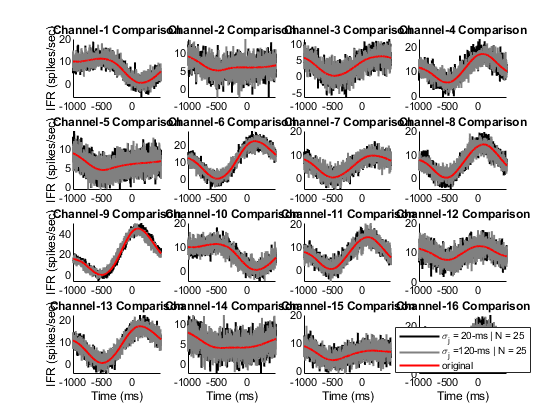

fig_all_averages = data.example.plot_sim_avg(X_low,X_high);

Notice that the **original **factor (red) matches both the **high-noise **and **low-noise **factors well.

#### (Optional) Save all trials average overview figure

 
figfile_all_avg = '';

thisChannel = 3

data.io.save_figure(figfile_all_avg,fig_all_averages);

# Check Individual-Trial Alignments

## Plot example single-channel traces overlay

### Select desired channel using slider

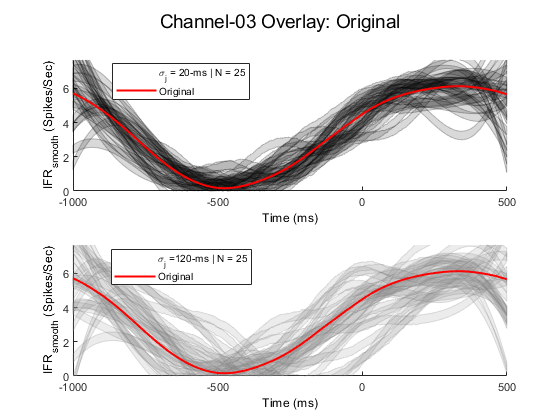

thisChannel = 3;
if exist('X_low','var')==0
    error(['Clean:' mfilename ':MissingVariables'],...

          ['\n\t[MAIN]: '...
           'Please click ' ...
           ''...
           'Run'...
           ' button first.']);
end

### We should smooth individual traces to make them easier to visualize

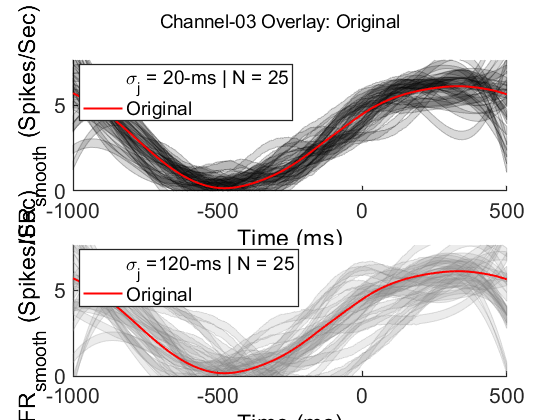


	->Example Original Output saved successfully.
		->(..\Figures\PCA-Alignment-Cleaning)


[Y_low,Y_high] = data.process.smooth(X_low,X_high);

fig_example_overlay = data.example.plot_channel_overlay(...
    thisChannel,'Original',Y_low,Y_high);

At this point, look at a few of the different channels, so you can convince yourself that there are misaligned peaks in individual trials, despite full-trial averages having relatively well-aligned peaks even thought hey only have a relatively low trial count.

*Insert reasons that it would be bad to have misaligned individual trials ****here****.*

#### (Optional) Save original simulation overlay figure

 
figfile_example_overlay_orig = 'Example Original Output';
data.io.save_figure(figfile_example_overlay_orig,fig_example_overlay);

# Apply Cleaning and Re-Check

## Plot example (cleaned) single-channel overlay

### Select % Variance to Reconstruct

reconstruction_var_captured = 96.49;
if exist('Y_low','var')==0
    error(['Clean:' mfilename ':MissingVariables'],...
          ['\n\t[MAIN]: ' ...
           'Please click '...
           '' ...
           'Run' ...
           ' button first.']);
end


	->Example Simulation saved successfully.
		->(..\Data\PCA-Alignment-Cleaning)


### "Clean" using PCA reconstruction

This is a three-step process:

- Concatenate trials through time (along "channels" axis so that each row contains all trials from 1 channel).

- Apply PCA to this concatenated matrix (similar to pre-processing for **jPCA**).

- Re-project to the original data using a reduced number of principal components (specified by `reconstruction_var_captured`).

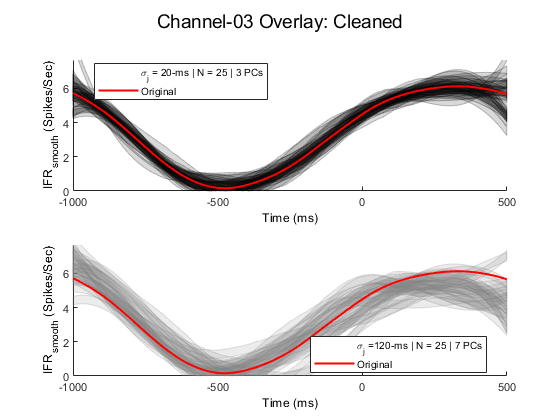

[Z_low,Z_high] = data.process.concat_trials(Y_low,Y_high);
[C_low,C_high] = data.process.clean(Z_low,Z_high,reconstruction_var_captured);

#### (Optional) Save output data

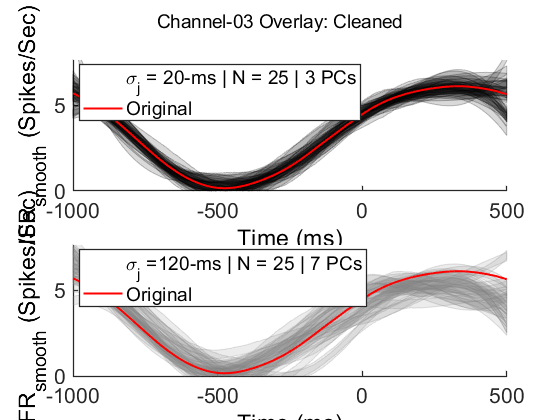

 
datafile = 'Example Simulation';
data.io.save_data(datafile,...
        X_low,Y_low,Z_low,C_low,...

        X_high,Y_low,Z_high,C_high,...
        nTrials,nChannels,nFactor_max,N,...
        thisChannel,reconstruction_var_captured);


### Plot smoothed, "cleaned" traces

fig_example_overlay_clean = data.example.plot_channel_overlay(...
    thisChannel,'Cleaned',C_low,C_high);

Notice how the peaks, particularly in the noisy case (**bottom subplot**) demonstrate a much-improved alignment on a per-trial basis. There is typically some attenuation in the maximum peak modulation, but overall, the tradeoff in terms of alignment seems to be a net-improved result.

#### (Optional) Save "cleaned" example overlay figure

 
figfile_example_overlay_clean = 'Example Cleaned Output';
data.io.save_figure(figfile_example_overlay_clean,...
    fig_example_overlay_clean);